# Contrast Enhancement Techniques

This example shows several image enhancement approaches. Three functions are particularly suitable for contrast enhancement: `imadjust`, `histeq`, and `adapthisteq`. This example compares their use for enhancing grayscale and truecolor images.

## Enhance Grayscale Images

Using the default settings, compare the effectiveness of the following three techniques:

- `imadjust` increases the contrast of the image by mapping the values of the input intensity image to new values such that, by default, 1% of the data is saturated at low and high intensities of the input data.

- `histeq` performs histogram equalization. It enhances the contrast of images by transforming the values in an intensity image so that the histogram of the output image approximately matches a specified histogram (uniform distribution by default).

- `adapthisteq` performs contrast-limited adaptive histogram equalization. Unlike `histeq`, it operates on small data regions (tiles) rather than the entire image. Each tile's contrast is enhanced so that the histogram of each output region approximately matches the specified histogram (uniform distribution by default). The contrast enhancement can be limited in order to avoid amplifying the noise which might be present in the image.

Read a grayscale image into the workspace. Enhance the image using the three contrast adjustment techniques.

pout = imread("C:\Repos\TopScanQt\build\DebugImages\channel_a.bmp");
pout_imadjust = imadjust(pout);
pout_histeq = histeq(pout);
pout_adapthisteq = adapthisteq(pout);

Display the original image and the three contrast adjusted images as a montage.

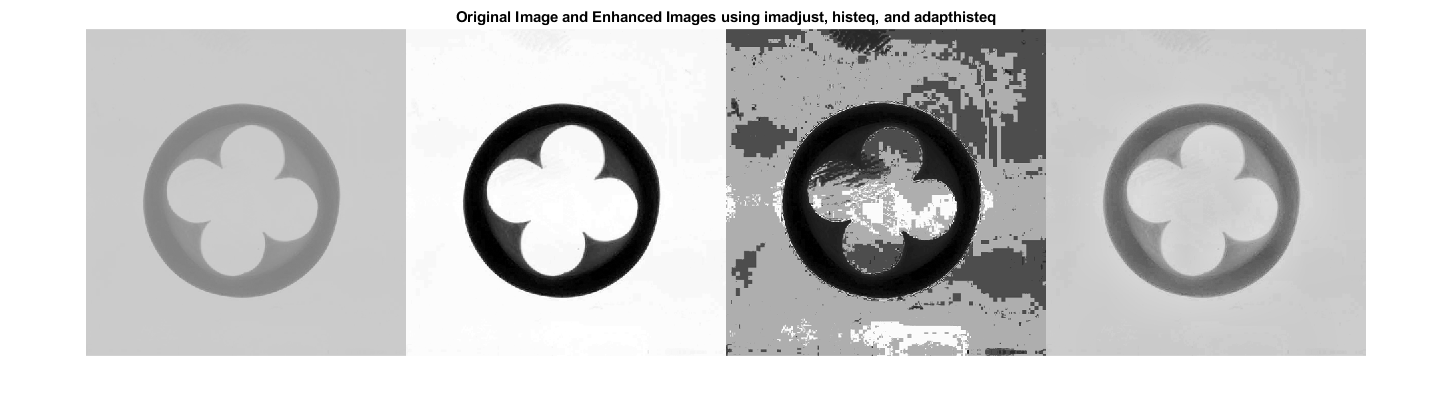

montage({pout,pout_imadjust,pout_histeq,pout_adapthisteq},'Size',[1 4])
title("Original Image and Enhanced Images using imadjust, histeq, and adapthisteq")

Read a second grayscale image into the workspace and enhance the image using the three contrast adjustment techniques.

tire = imread('tire.tif');
tire_imadjust = imadjust(tire);
tire_histeq = histeq(tire);
tire_adapthisteq = adapthisteq(tire);

Display the original image and the three contrast adjusted images as a montage.

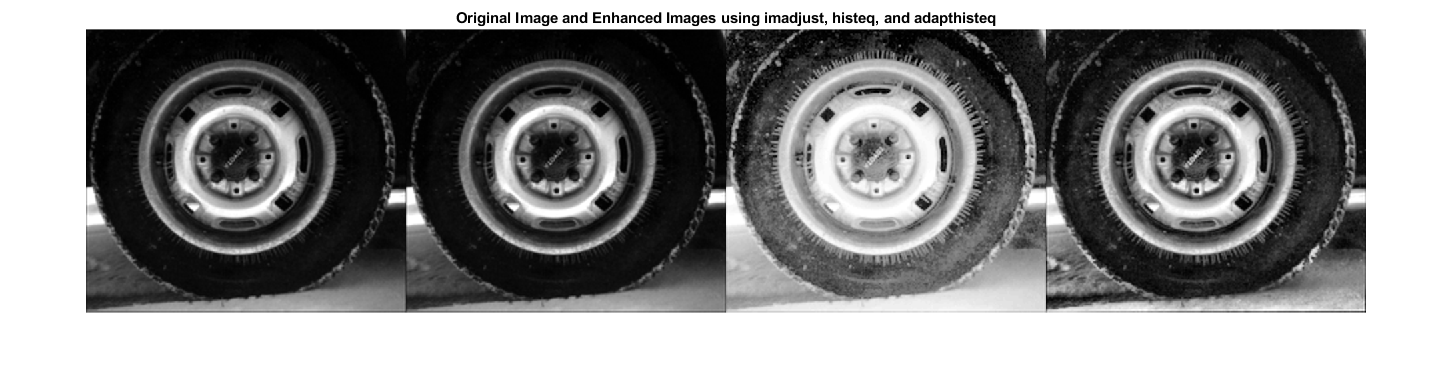

montage({tire,tire_imadjust,tire_histeq,tire_adapthisteq},'Size',[1 4])
title("Original Image and Enhanced Images using imadjust, histeq, and adapthisteq")

Notice that `imadjust` had little effect on the image of the tire, but it caused a drastic change in the case of pout. Plotting the histograms of `pout.tif` and `tire.tif` reveals that most of the pixels in the first image are concentrated in the center of the histogram, while in the case of `tire.tif`, the values are already spread out between the minimum of 0 and maximum of 255 thus preventing  `imadjust` from being effective in adjusting the contrast of the image.

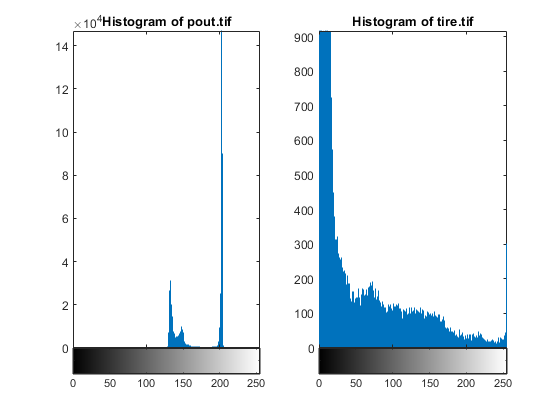

figure
subplot(1,2,1)
imhist(pout)
title('Histogram of pout.tif')
subplot(1,2,2)
imhist(tire)
title('Histogram of tire.tif');

Histogram equalization, on the other hand, substantially changes both images. Many of the previously hidden features are exposed, especially the debris particles on the tire. Unfortunately, at the same time, the enhancement over-saturates several areas of both images. Notice how the center of the tire, part of the child's face, and the jacket became washed out.

Concentrating on the image of the tire, it would be preferable for the center of the wheel to stay at about the same brightness while enhancing the contrast in other areas of the image. In order for that to happen, a different transformation would have to be applied to different portions of the image. The Contrast-Limited Adaptive Histogram Equalization technique, implemented in `adapthisteq`, can accomplish this. The algorithm analyzes portions of the image and computes the appropriate transformations. A limit on the level of contrast enhancement can also be set, thus preventing the over-saturation caused by the basic histogram equalization method of `histeq`. This is the most sophisticated technique in this example.

## Enhance Color Images

Contrast enhancement of color images is typically done by converting the image to a color space that has image luminosity as one of its components, such as the L*a*b* color space. Contrast adjustment is performed on the luminosity layer 'L*' only, and then the image is converted back to the RGB color space. Manipulating luminosity affects the intensity of the pixels, while preserving the original colors.

Read an image into the workspace. The `'shadow.tif'` image is an indexed image, so convert the image to a truecolor (RGB) image. Then, convert the image from the RGB color space to the L*a*b* color space.

[X,map] = imread('shadow.tif');
shadow = ind2rgb(X,map); 

Index in position 1 exceeds array bounds.

Error in ind2rgb (line 26)
r = zeros(size(a)); r(:) = cm(a,1);

shadow_lab = rgb2lab(shadow);

The values of luminosity span a range from 0 to 100. Scale the values to the range [0 1], which is the expected range of images with data type `double`.

max_luminosity = 100;
L = shadow_lab(:,:,1)/max_luminosity;

Perform the three types of contrast adjustment on the luminosity channel, and keep the a* and b* channels unchanged. Convert the images back to the RGB color space.

shadow_imadjust = shadow_lab;
shadow_imadjust(:,:,1) = imadjust(L)*max_luminosity;
shadow_imadjust = lab2rgb(shadow_imadjust);

shadow_histeq = shadow_lab;
shadow_histeq(:,:,1) = histeq(L)*max_luminosity;
shadow_histeq = lab2rgb(shadow_histeq);

shadow_adapthisteq = shadow_lab;
shadow_adapthisteq(:,:,1) = adapthisteq(L)*max_luminosity;
shadow_adapthisteq = lab2rgb(shadow_adapthisteq);

Display the original image and the three contrast adjusted images as a montage.

figure
montage({shadow,shadow_imadjust,shadow_histeq,shadow_adapthisteq},'Size',[1 4])
title("Original Image and Enhanced Images using imadjust, histeq, and adapthisteq")

*Copyright 1993-2018 The MathWorks, Inc.*